3(a)

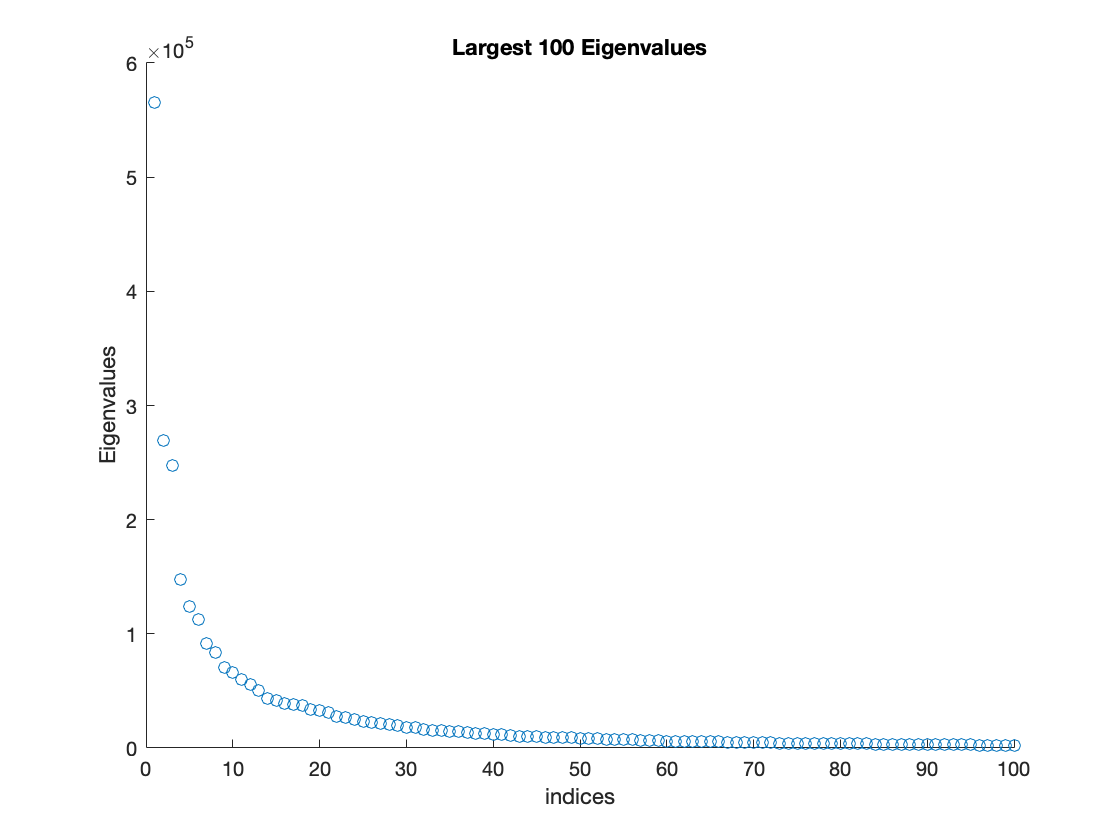

x = readtable('MNIST5.csv');
x = x{:,:};
covar = cov(x, 1);
[V, D] = eig(covar);
[D, ind] = sort(diag(D), 'descend');
V = V(:,ind);
figure(1);
scatter(1:100, D(1:100));
ylabel('Eigenvalues');
xlabel('indices');
title('Largest 100 Eigenvalues');

(b)

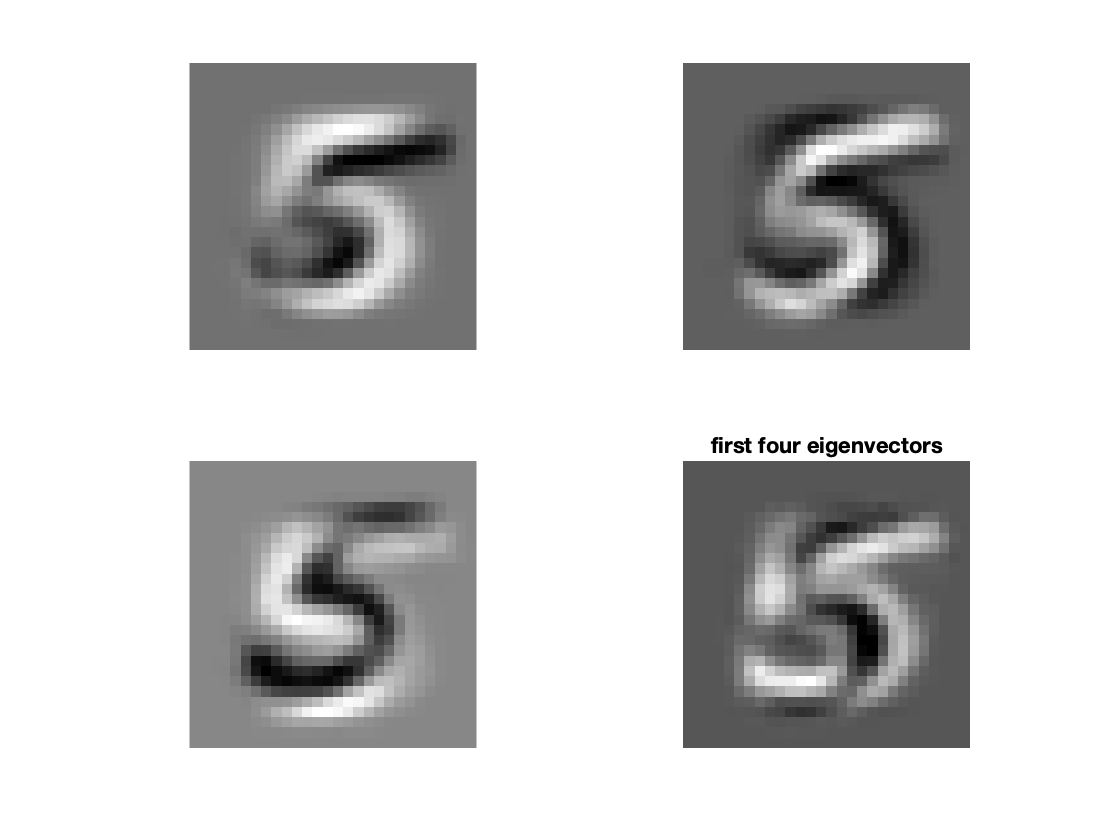

figure(2);
for i = 1:4
    img = cast(rescale(reshape(V(:,i), [28, 28]), 0, 255), 'uint8');
    subplot(2,2,i);
    imshow(img);
end
title('first four eigenvectors');

(c)

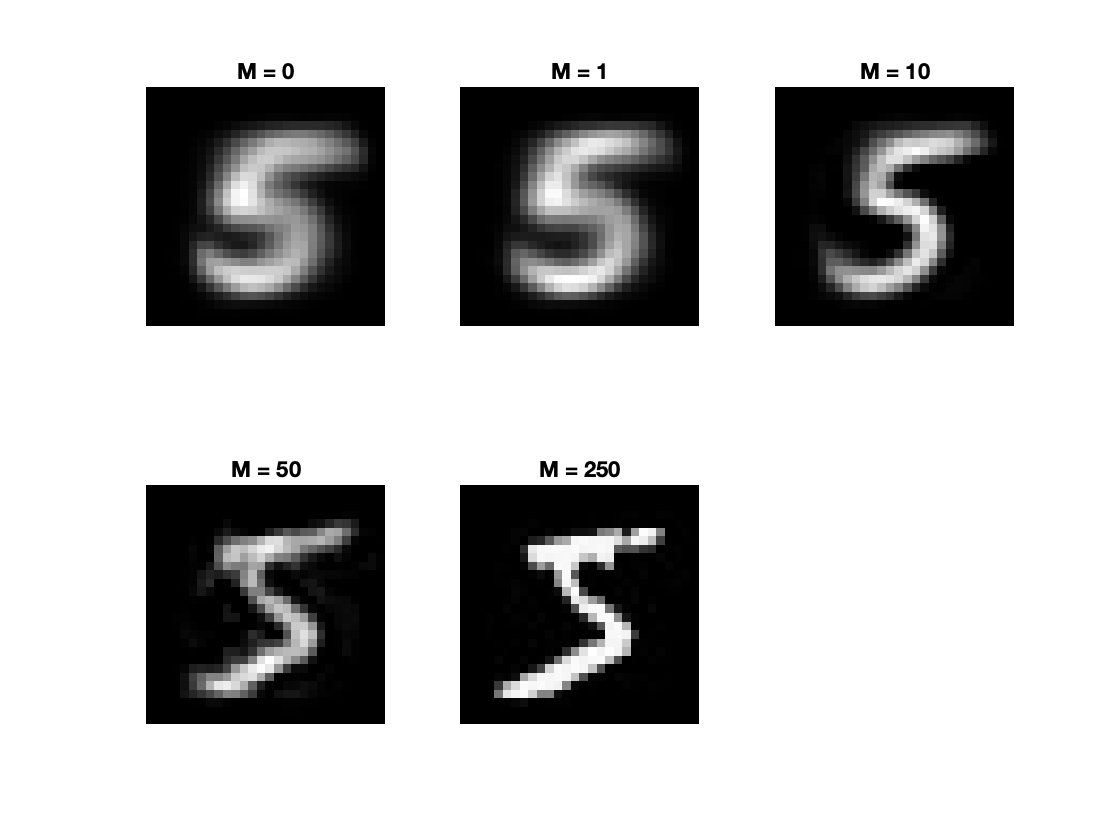

figure(3);
xbar = mean(x, 1);
M = [0;1;10;50;250];
for n = 1:5
    m = M(n);
    xtil = xbar;
    for i = 1:m
        xtil = xtil + (x(1,:) * V(:,i) - xbar * V(:,i)) * V(:,i)';
    end
    subplot(2,3,n),imshow(cast(reshape(xtil, [28, 28]) * 255 / max(xtil), 'uint8'));
    title("M = "+ m);
end

M = 250 is very clear. As M increases it looks like the quality of the image increases and the 5 becomes more distinctive. 

when M = 0, it is just the mean vector of all of the test cases.